# Возможности функции "pspectrum"

clear; close all;

## 1. Фурье-анализ всего сигнала

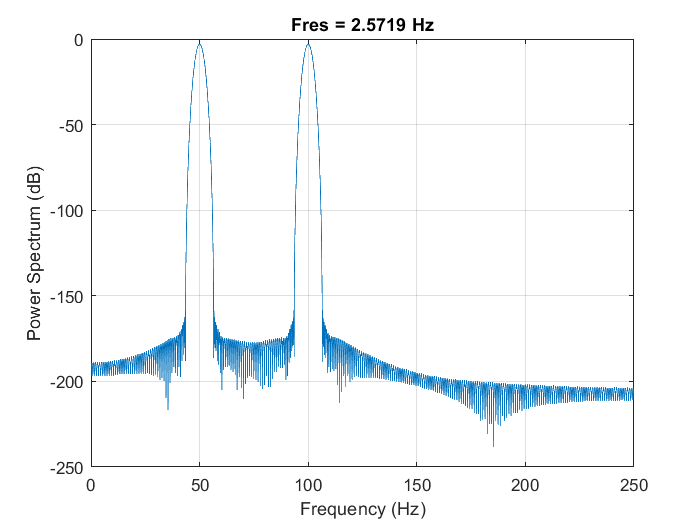

f0 = 100;
fs = 5*f0;
dt = 1/fs;
t  = 0:dt:100/f0-dt;

x  = cos(2*pi*f0*t)+cos(2*pi*f0/2*t+pi);
pspectrum(x,fs);

## 2. Вычисление спектра всего сигнала

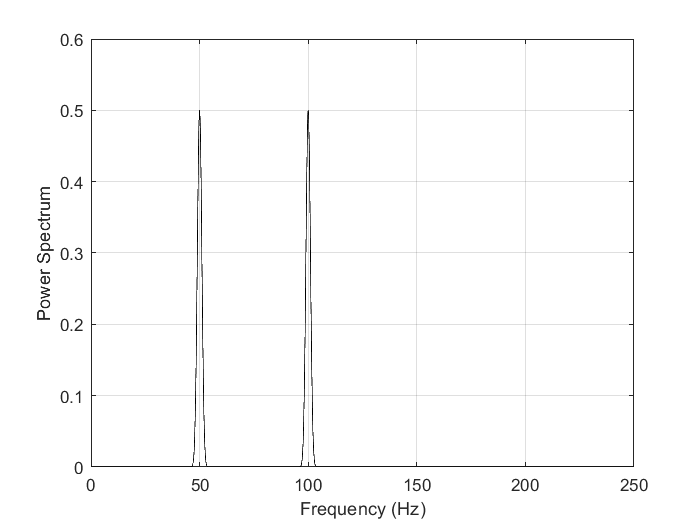

f0 = 100;
fs = 5*f0;
dt = 1/fs;
t  = 0:dt:100/f0-dt;

x     = cos(2*pi*f0*t)+cos(2*pi*f0/2*t+pi);
[X,f] = pspectrum(x,fs);

plot(f,X,'-k'); grid on;
xlabel('Frequency (Hz)');
ylabel('Power Spectrum');

## 3. Построение спектрограммы

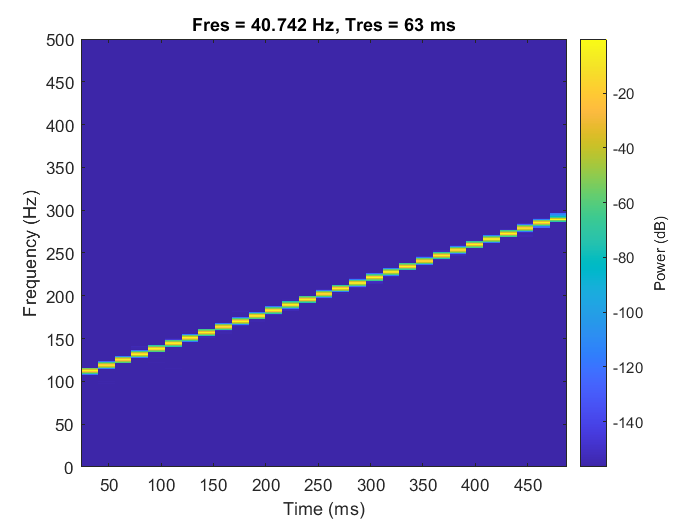

f0 = 100;
fs = 10*f0;
dt = 1/fs;
t  = 0:dt:50/f0-dt;

x  = chirp(t,f0,t(end),3*f0);
pspectrum(x,fs,'spectrogram','Reassign',true);